Let's repeat the experiment of the previous figure for more, and larger, values of $n$.

n_ = (400:200:6000)';
t_ = 0*n_;
for i = 1:length(n_)
    n = n_(i);
    A = randn(n,n);  x = randn(n,1);
    tic  % start a timer
    for j = 1:10  % repeat ten times
        A*x;
    end
    t = toc;  % read the timer
    t_(i) = t/10;  
end

Plotting the time as a function of $n$ on log-log scales is equivalent to plotting the logs of the variables, but is formatted more neatly. 

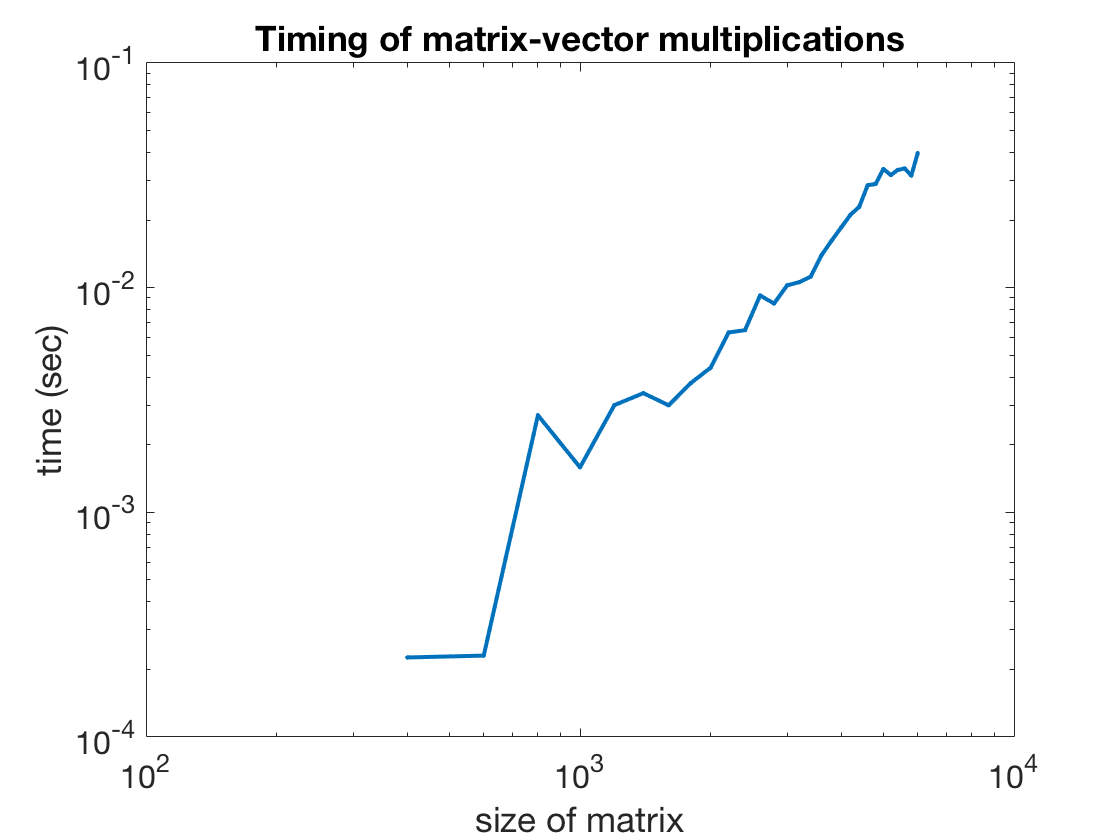

loglog(n_,t_,'.-')
xlabel('size of matrix'), ylabel('time (sec)')
title('Timing of matrix-vector multiplications')

You can see that the graph is trending to a straight line of positive slope. For comparison, we can plot a line that represents $O(n^2)$ growth exactly. (All such lines have slope equal to 2.)

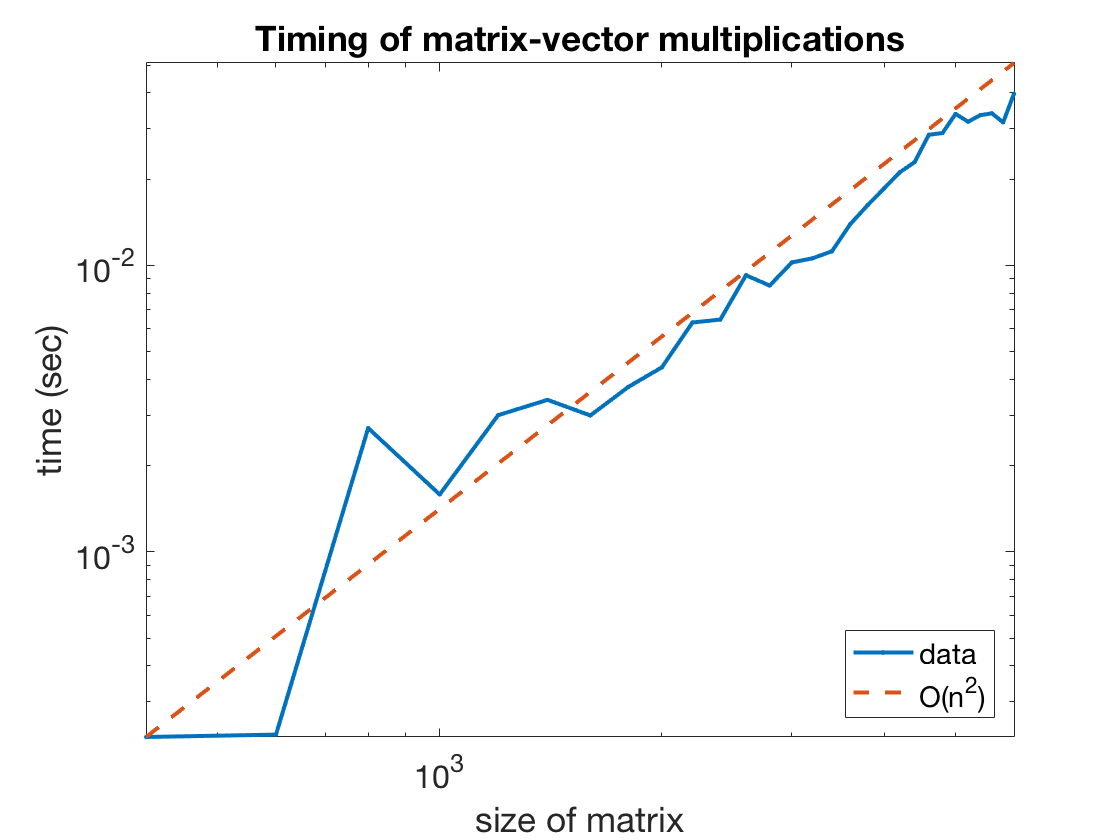

hold on, loglog(n_,t_(1)*(n_/n_(1)).^2,'--')
axis tight
legend('data','O(n^2)','location','southeast')

The full story of the execution times is complicated, but the asymptotic approach to $O(n^2)$ is unmistakable.